# **Haberleşme Kanalında Veri İletimi**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## **1) VERİCİ TASARIMI**

Bir haberleşme sisteminin çalışma mekanizmasını anlamak için önce sistemin en temel bileşenini öğrenmemiz gerekiyor:

***SORU-1:*** Veri nedir?

***CEVAP:*** Bir haberleşme sisteminde verici tarafından alıcıya gönderilen **herhangi bir yararlı bilgiye** veri denmektedir. Bu bilgi bir görüntü, bir ses veya yazılı bir mesaj olabilir.

***SORU-2:*** Veri iletiminin gerçekleşmesi için verilerin hangi formatta olması gerekir?

***CEVAP:*** Hem analog hem de sayısal haberleşme literatürde mevcut olmakla beraber günümüz teknolojisinde veriler büyük çoğunlukla **sayısal formatta yani bit paketleri halinde** iletilirler.

***SORU-3:*** Veriler sayısal formata nasıl getirilirler?

***CEVAP:*** Verilerin dijitalleştirilmesi veri tipine göre değişiklik göstermektedir.

### **1.1) Verilerin Dijitalleştirilmesi**

#### ***1.1.1) Görüntü Verisinin Dijitalleştirilmesi***

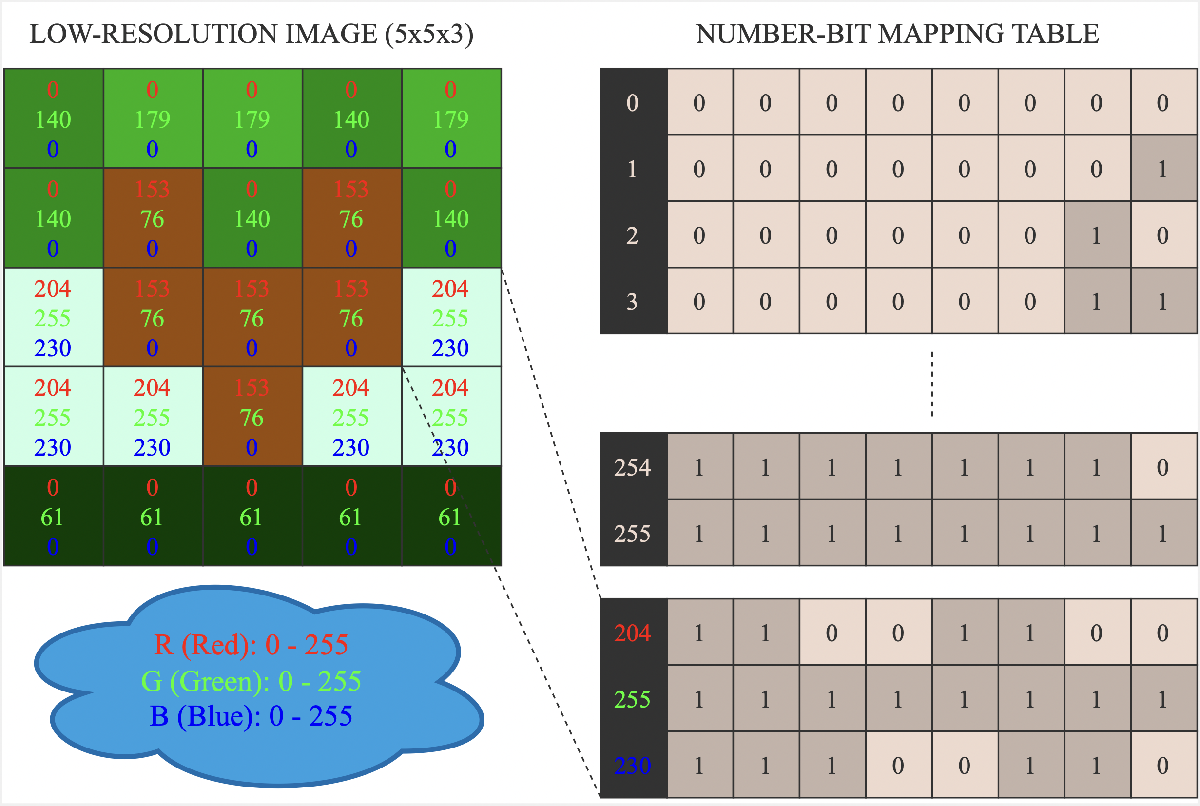

clear all;
clc;

low_res_image = imread("Image Files/low_res_tree.png");
fprintf(num2str(size(low_res_image)));
fprintf(num2str(low_res_image(1, 1, :)));
image_bit_array = Im2Bit(low_res_image);
fprintf(num2str(length(image_bit_array)));
figure;
imshow(low_res_image, "InitialMagnification", "fit");

#### *1.1.2) Televizyon Çözünürlük Değerleri*

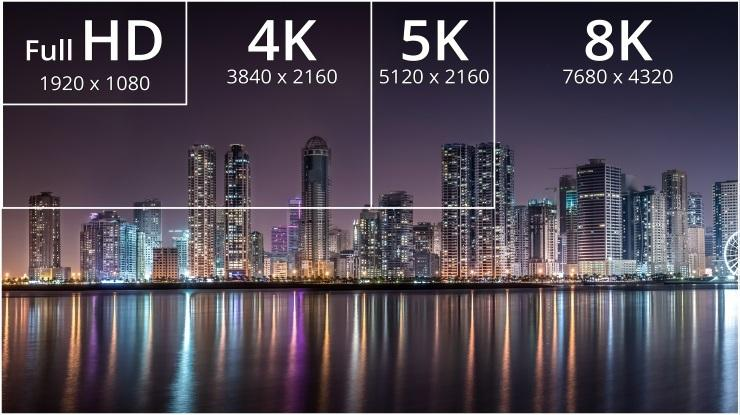

Görüntü PCMag'a aittir.

#### *1.1.3) Ses Verisinin Dijitalleştirilmesi*

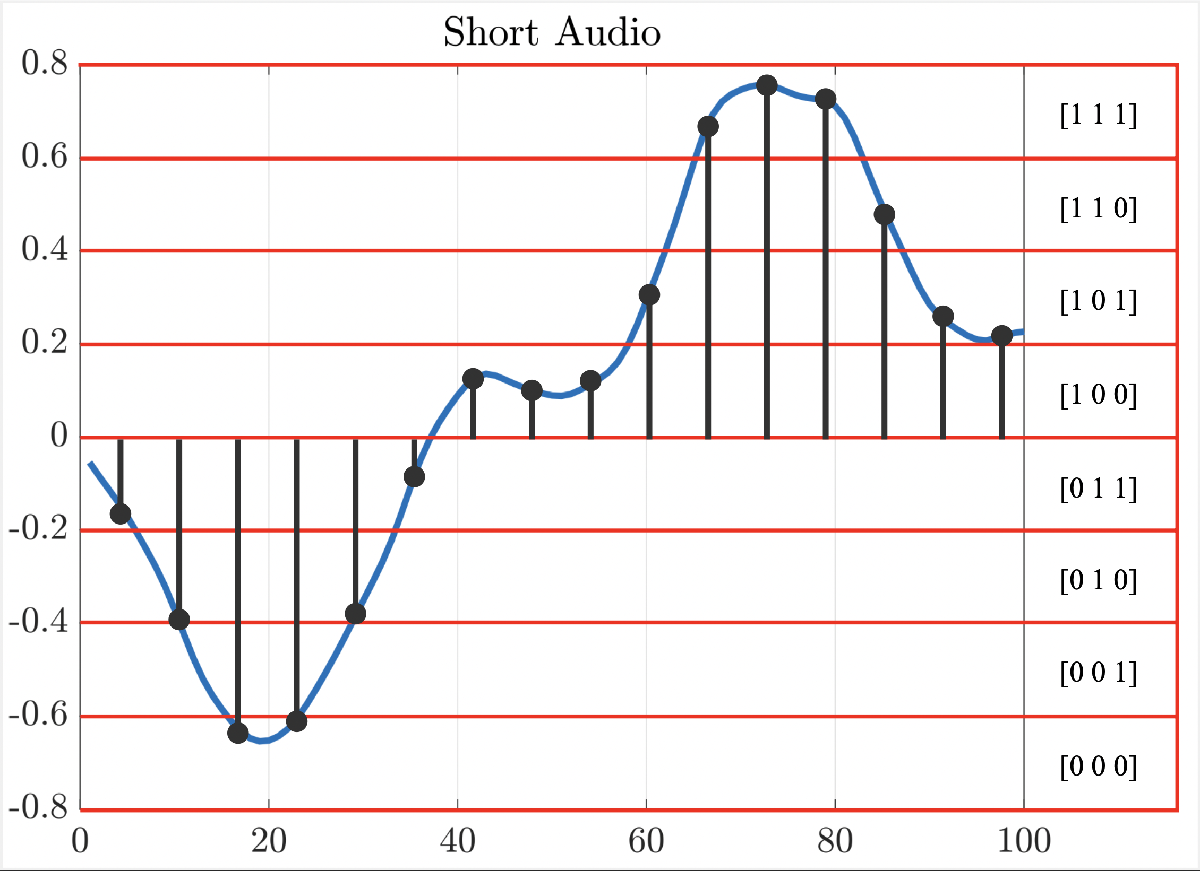

***SORU-4:*** Veriler sayısal formata getirildikten sonra nasıl iletilirler?

***CEVAP:*** Sayısal veriler, yani bilgi bitleri, **modülasyon** işlemi ile bir taşıyıcıya yüklenir ve haberleşme ortamına iletilir.

### 1.2) Modülasyon

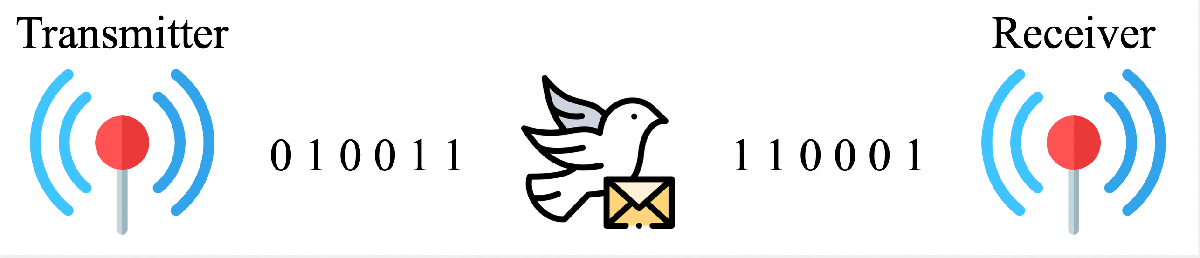

#### *1.2.1) Kosinüs İşaretinin Özellikleri*

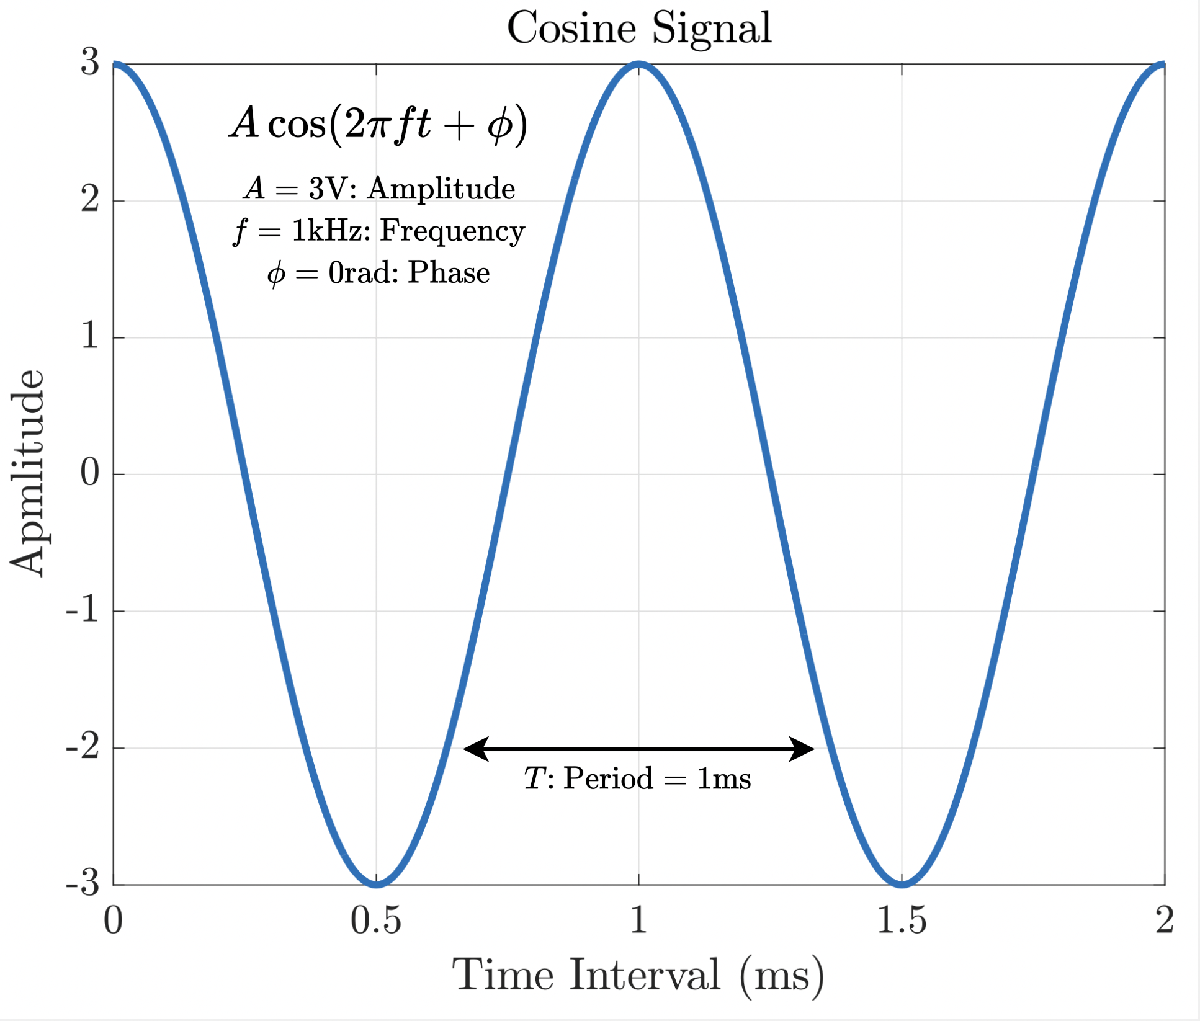

clear all;
clc;

% Three Features of a Cosine Signal///////////////
A = 3; % Amplitude = 3V
f = 1000; % Frequency = 1000Hz = 1kHz
phi = 0; % Phase = 0rad
% ////////////////////////////////////////////////

T = 1 / f; % Period = 0.001s = 1ms
k = 2; % Number of periods in the given time interval
t = 0 : 1e-8 : k * T; % Time interval for k periods
cos_signal = A * cos(2 * pi * f * t + phi); % Cosine signal
figure;
plot(t * 1000, cos_signal, "LineWidth", 3);
set(gca, "FontSize", 17);
set(gca, "TickLabelInterpreter", "latex");
title("Cosine Signal", "Interpreter", "latex");
xlabel("Time Interval (ms)", "Interpreter", "latex");
ylabel("Amplitude (V)", "Interpreter", "latex");
grid;

#### *1.2.2) Modülasyon Çeşitleri*

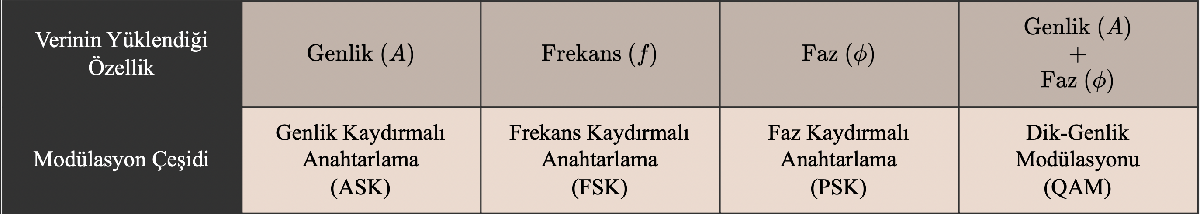

***SORU-5: ***Modülasyon işlemi sırasında bilgi bitleri taşıyıcı işarete nasıl yüklenir?

***CEVAP:*** Veriler hangi özelliğe yüklenecekse, bilgi bitlerine göre o özellik farklı bir değer alır.

#### ***1.2.3) Faz Kaydırmalı Anahtarlama (Phase Shift Keying, PSK)***

Bir iletim zamanında bir bit iletildiği varsayılsın. Bu durumda, bir iletim zamanında ya $0$, ya da $1$ biti iletilebilir ve **modülasyon seviyesi** $M=2$ olur. PSK uygulanırken bilgi bitleri taşıyıcı işaretin fazına yükleneceği için bu iki seviye için iki farklı faz değeri tanımlanır:

- $1$ biti için faz: $\phi = 0$ rad $\rightarrow$ Taşıyıcı işaret: $\cos(2 \pi ft + 0) = \cos(2 \pi ft) = s_{1}(t)$ (1 sembolü)

- $0$ biti için faz: $\phi = \pi$ rad $\rightarrow$ Taşıyıcı işaret: $\cos(2 \pi ft + \pi) = -\cos(2 \pi ft) = -s_{1}(t)$ (-1 sembolü)

clear all;
clc;

A = 1; % Amplitude = 1V
f = 1000; % Frequency = 1000Hz = 1kHz
phi_0 = pi; % Phase of the carrier signal for bit-0
phi_1 = 0; % Phase of the carrier signal for bit-1

T = 1 / f; % Period = 0.001s = 1ms
k = 2; % Number of periods in the given time interval
t = 0 : 1e-8 : k * T; % Time interval for k periods

cos_signal_0 = A * cos(2 * pi * f * t + phi_0); % Carrier signal for bit-0
cos_signal_1 = A * cos(2 * pi * f * t + phi_1); % Carrier signal for bit-1

figure;
plot(t * 1000, cos_signal_0, "LineWidth", 3);
hold on;
plot(t * 1000, cos_signal_1, "LineWidth", 3);
set(gca, "FontSize", 17);
set(gca, "TickLabelInterpreter", "latex");
title("Carrier Signals", "Interpreter", "latex");
xlabel("Time Interval (ms)", "Interpreter", "latex");
ylabel("Amplitude (V)", "Interpreter", "latex");
legend("Bit-0 ($\phi = \pi$ rad)",...
       "Bit-1 ($\phi = 0$ rad)",...
       "Location", "northeast", "FontSize", 17, "Interpreter", "latex");
grid;

Bir iletim zamanında bir bitin iletildiği iki seviyeli PSK özel olarak **ikili PSK (binary PSK, BPSK)** olarak adlandırılır. Örnek bir bilgi biti dizisi, $[\matrix{
1 & 0 & 1 & 0 & 0
}
]$, için taşıyıcı işaret aşağıdaki gibi elde edilebilir:

clear all;
clc;

A = 1; % Amplitude = 3V
f = 1000; % Frequency = 1000Hz = 1kHz
bit_array = [1 0 1 0 0]; % Data bit array
phi_array = (bit_array - 1) * -pi; % Phase array corresponding to data bits

T = 1 / f; % Period = 0.001s = 1ms
k = 1; % Number of periods in the given time interval
t = 0 : 1e-8 : k * T; % Time interval for k periods

cos_signal_matrix = A * cos(2 * pi * f * t + phi_array.'); % Carrier signals
% corresponding to each data bit

figure;
plot(t * 1000, cos_signal_matrix(1, :), "LineWidth", 3);
hold on;
plot((t + k * T + 1e-8) * 1000, cos_signal_matrix(2, :), "LineWidth", 3);
hold on;
plot((t + 2 * k * T + 2e-8) * 1000, cos_signal_matrix(3, :), "LineWidth", 3);
hold on;
plot((t + 3 * k * T + 3e-8) * 1000, cos_signal_matrix(4, :), "LineWidth", 3);
hold on;
plot((t + 4 * k * T + 4e-8) * 1000, cos_signal_matrix(5, :), "LineWidth", 3);
hold on;
plot([1, 1], [-1, 1], "k--", "LineWidth", 3);
hold on;
plot([2, 2], [-1, 1], "k--", "LineWidth", 3);
hold on;
plot([3, 3], [-1, 1], "k--", "LineWidth", 3);
hold on;
plot([4, 4], [-1, 1], "k--", "LineWidth", 3);
set(gca, "FontSize", 17);
set(gca, "TickLabelInterpreter", "latex");
title("Carrier Signal For [1 0 1 0 0]", "Interpreter", "latex");
xlabel("Time Interval (ms)", "Interpreter", "latex");
ylabel("Amplitude (V)", "Interpreter", "latex");
xlim([0, 5]);
grid;

## 2) KANAL YAPISI

***SORU-6:*** Veri iletimi sırasında taşıyıcı işaret hangi ortamdan ilerler ve ortam taşıyıcı işareti nasıl etkiler?

***CEVAP:*** Veri iletiminin gerçekleştiği ortama kanal denir ve bir haberleşme kanalı en üst çerçevede **kablolu (wired) veya kablosuz (wireless) kanal** olarak ikiye ayrılır. Bu kanalların taşıyıcı işarete etkisi aşağıda verildiği gibi olur:

- **Kablolu Kanal**: Kablodaki ve alıcı antendeki fiziksel bozulmalardan dolayı taşıyıcı işaretin **üzerine** **ısıl gürültü** **biner**.

- **Kablosuz Kanal**: Taşıyıcı işaret çevredeki farklı objelerden yansıma yapar ve böylece alıcıya taşıyıcı işaretin birçok kopyası ulaşır. Bu kopyalar birbirleri üzerinde bozucu etki yapar ve bu duruma sönümleme (fading) denir. Bunun yanında alıcı antendeki fiziksel bozulmalardan dolayı kablolu kanalda olduğu gibi taşıyıcı işaretin üzerine ısıl gürültü de eklenir. Sonuç olarak, kablosuz kanalda taşıyıcı işaret **hem sönümlenir **hem de taşıyıcı işaretin** üzerine ısıl gürültü biner**.

### 2.1) Kablolu Kanal

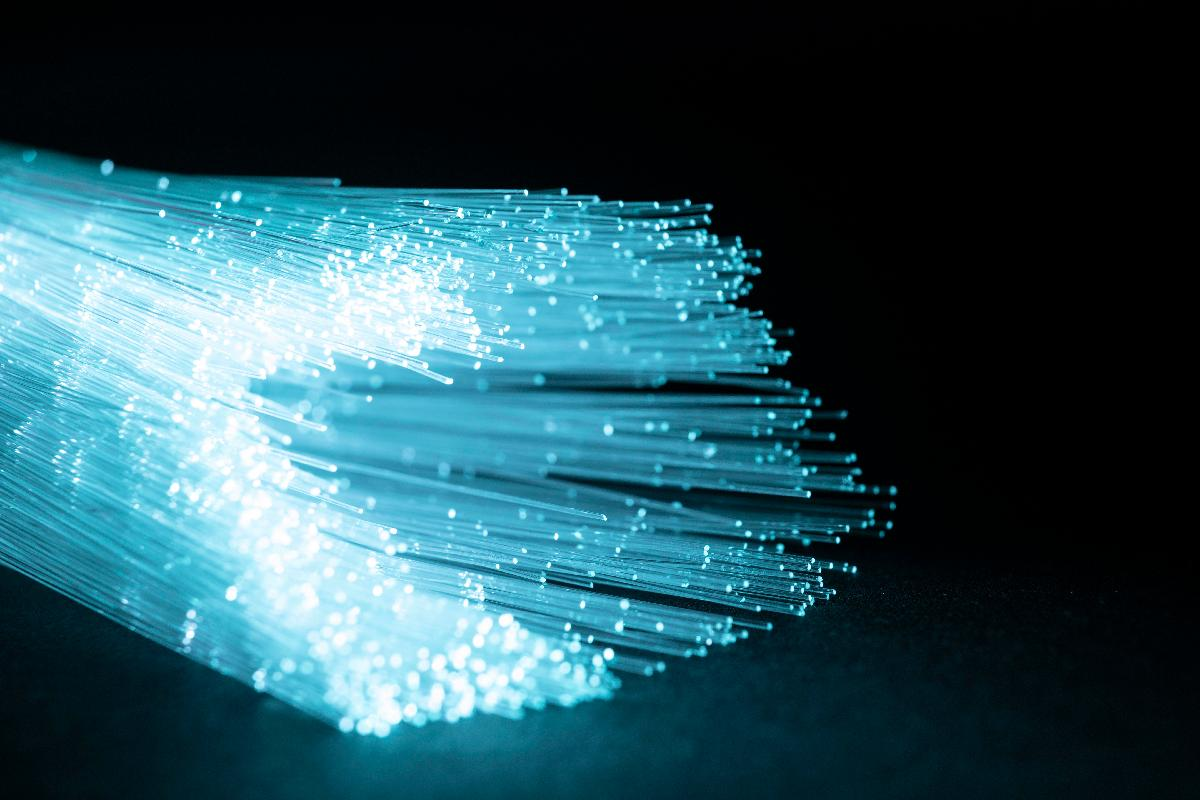

Kablolu kanalda taşıyıcı işaret üzerine yalnızca ısıl gürültü biner. Bu gürültü sıfır ortalamalı ve Gauss dağılımlı bir rastlantı değişkenidir. Bu sebepten ısıl gürültü literatürde **toplamsal beyaz Gauss gürültüsü (additive white Gaussian noise, AWGN)** olarak, kablolu kanal da literatürde **AWGN kanal** olarak bilinir.

clear all;
clc;

figure;
n = randn(1, 1e5);
h1 = histogram(n);
h1.Normalization = "pdf";
set(gca, "FontSize", 17);
set(gca, "TickLabelInterpreter", "latex");
title("Gaussian Distribution", "Interpreter", "latex");
grid;

### 2.2) Kablosuz Kanal

## 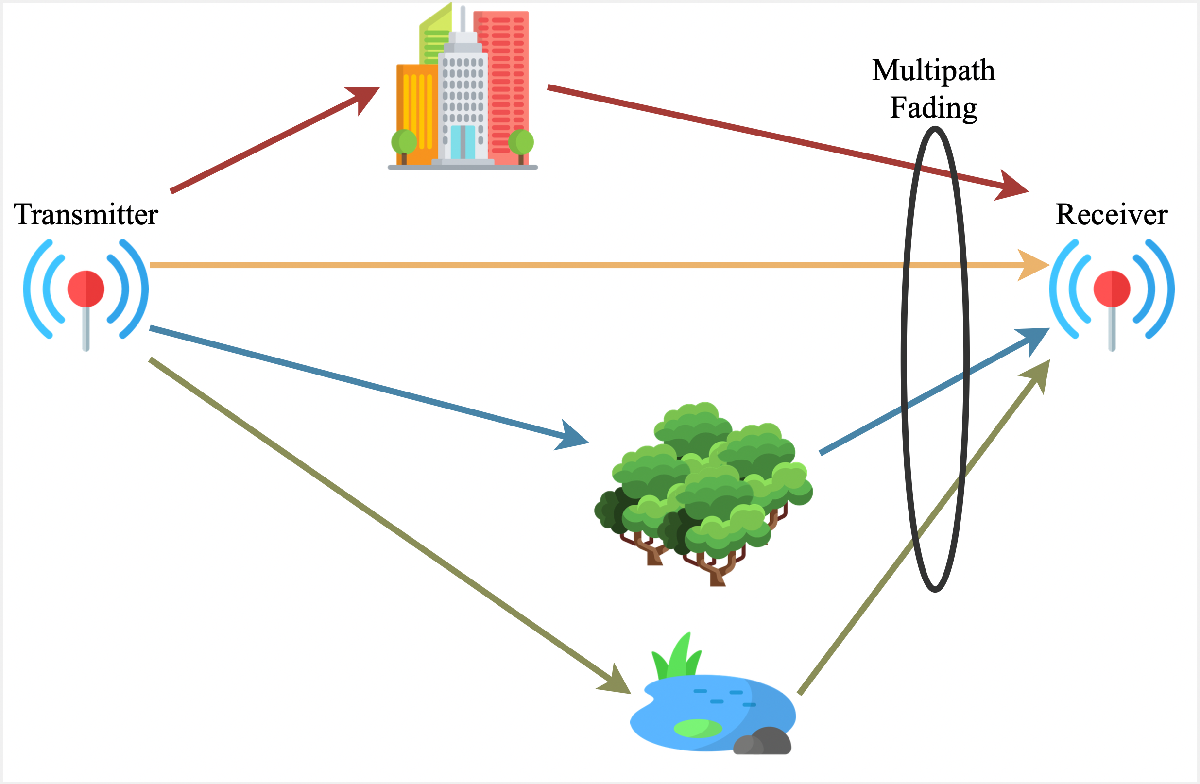

## **3) GÖRÜNTÜ İLETİMİ**

clear all;
clc;

input_image = imread("Image Files/owl.jpg");
figure;
imshow(input_image);

M = 4;
mod_type = "PSK";
ini_phase = 0;
figure;
DisplayConstellation(M, mod_type, ini_phase);

SNRdB =-3;
channel_type = "AWGN";
[num_symbols, Image_BER, output_image] = ImageTransmission(input_image, M, mod_type, SNRdB, channel_type);
fprintf("İletim için gerekli zaman: %f saniye", num_symbols / 1e6);
figure;
imshow(output_image);

## 4) SES İLETİMİ

clear all;
clc;

audio_type = "Read";
if audio_type == "Read"
    audio_file = "Fatih Terim Italyanca";
    [input_stereo_array, sampling_rate] = audioread(strcat("Audio Files/", audio_file, ".mp3"));
    input_audio_array = reshape(input_stereo_array, [1, numel(input_stereo_array)]);
    sound(input_stereo_array, sampling_rate);
elseif audio_type == "Record"
    rec_object = audiorecorder;
    rec_duration = 5;
    recordblocking(rec_object,rec_duration);
    input_audio_array = getaudiodata(rec_object).';
    sampling_rate = 8000;
    sound(input_audio_array, sampling_rate);
end

M = 2;
mod_type = "PSK";
ini_phase = 0;
DisplayConstellation(M, mod_type, ini_phase);

SNRdB =-50;
channel_type = "AWGN";
[num_symbols, Audio_BER, output_stereo_array] = AudioTransmission(input_audio_array, M, mod_type, SNRdB, channel_type);
fprintf("İletim için gerekli zaman: %f saniye", num_symbols / 1e6);
sound(output_stereo_array, sampling_rate);

## 5) SORU - CEVAP